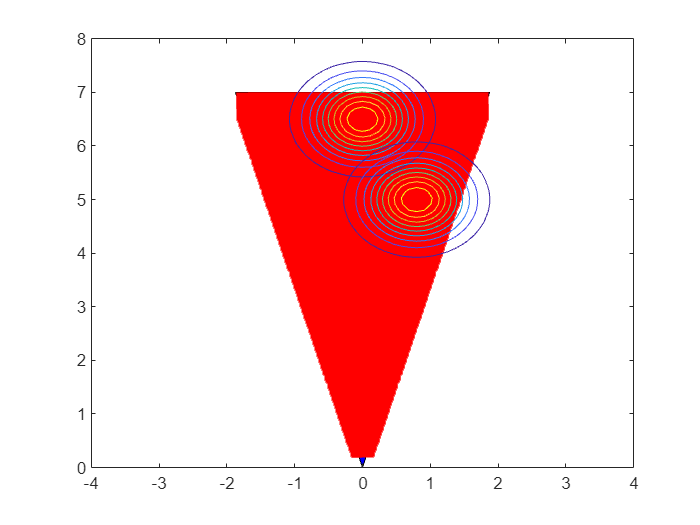

clear;clc;close;

% Parameter
range = 5; lambda = 2; AOV = pi/6; alpha = AOV*0.5;
pos = [0;0]; perspective = [0;1]; perspective = perspective/norm(perspective);

range_max = ( (lambda+1)/lambda )*range*cos(alpha);
R = [cos(alpha) -sin(alpha);sin(alpha) cos(alpha)];

top = pos + range_max*perspective;
ltop = pos + range_max*( R*perspective );
rtop = pos + range_max*( (R')*perspective);

% Event & Joint Probability
p0 = 0.3;
P = @(d, a) ( ((d-range_max).^2).*((a-alpha).^2) )./( (range_max.^2).*(alpha.^2) );
% p_ = @(d, a) ( ((d).^2).*((a).^2) )./( (range_max.^2).*(alpha.^2) );

P_ = @(d, a) p0.*exp( -((d-range_max).^2 )./(2*0.5^2) ).*exp( -((a-alpha).^2 )./(2*0.5^2) );
% p_ = @(d, a) exp( -((d-range_max).^2 + (a-alpha).^2)./(2*0.36^2) );

f1 = @(x) exp( -(vecnorm(x-[0;6.5])).^2./(2*0.5^2) );
f1_ = @(x, y) exp( -( (x-0).^2 + (y-6.5).^2 )./(2*0.5^2) );
f2 = @(x) exp( -(vecnorm(x-[0.8;5])).^2./(2*0.5^2) );
f2_ = @(x, y) exp( -( (x-0.8).^2 + (y-5).^2 )./(2*0.5^2) );
f3 = @(x) exp( -(vecnorm(x-[-0.8;5])).^2./(2*0.5^2) );
f3_ = @(x, y) exp( -( (x+0.8).^2 + (y-5).^2 )./(2*0.5^2) );

% Plot
% Define the vertices of the triangle
A = [pos(1) pos(2)];
B = [ltop(1) ltop(2)];
C = [rtop(1) rtop(2)];

% Define the x and y ranges with a spacing of 0.1
x_range = ltop(1)+0.1:0.01:rtop(1)-0.1;
y_range = 0.3:0.01:rtop(2)-0.1;

% Generate a grid of points within the x and y ranges
[X, Y] = meshgrid(x_range, y_range);

% Reshape the grid into a list of points
points = [X(:) Y(:)];

% Select only the points within the triangle
in_triangle = inpolygon(points(:,1), points(:,2), [A(1) B(1) C(1)], [A(2) B(2) C(2)]);
points = points(in_triangle, :);

% Plot the triangle and the generated points
figure;
fill([A(1) B(1) C(1)], [A(2) B(2) C(2)], 'blue');
hold on;
plot(points(:,1), points(:,2), 'rx', 'MarkerSize', 10);
fcontour(f1_);
fcontour(f2_);
% fcontour(f3_);
hold off
xlim([-4 4]); ylim([0 8]);

% Point
FOV = points';
d_W = vecnorm(FOV-pos);
a_W = acos( ((FOV-pos)./d_W)'*perspective );

% Define the size of the square area and the spacing between points
L = 8; % length of the square
d = 8; % spacing between points

% Define the x and y ranges with a spacing of d
x_range = -L/2:0.01:L/2;
y_range = 0:0.01:d;

% Generate a grid of points within the x and y ranges
[X, Y] = meshgrid(x_range, y_range);

% Reshape the grid into a list of points
W = [X(:) Y(:)]';

% Probability
JP_W = P(d_W, a_W');
F1_W = f1(FOV);
F2_W = f2(FOV);
F3_W = f3(FOV);
H_W = sum(F1_W.*JP_W)+sum(F2_W.*JP_W)+sum(F3_W.*JP_W);

JP_W_I = P_(d_W, a_W');
H_W_I = sum(F1_W.*JP_W_I)+sum(F2_W.*JP_W_I)+sum(F3_W.*JP_W_I);